% Check that WLAN Toolbox is installed, and that there is a valid license
if isempty(ver('wlan')) % Check for WLAN Toolbox install
    error('Please install WLAN Toolbox to run this example.');
elseif ~license('test', 'WLAN_System_Toolbox') % Check that a valid license is present
    error( ...
        'A valid license for WLAN Toolbox is required to run this example.');
end

% Setup handle for image plot
if ~exist('imFig', 'var') || ~ishandle(imFig)
    imFig = figure;
    imFig.NumberTitle = 'off';
    imFig.Name = 'Image Plot';
    imFig.Visible = 'off';
else
    clf(imFig); % Clear figure
    imFig.Visible = 'off';
end

% Setup Spectrum viewer
spectrumScope = dsp.SpectrumAnalyzer( ...
    'SpectrumType',    'Power density', ...
    'SpectralAverages', 10, ...
    'YLimits',         [-130 -40], ...
    'Title',           'Received Baseband WLAN Signal Spectrum', ...
    'YLabel',          'Power spectral density');

% Setup the constellation diagram viewer for equalized WLAN symbols
constellation = comm.ConstellationDiagram('Title','Equalized WLAN Symbols',...
                                'ShowReferenceConstellation',false);

% Input an image file and convert to binary stream
fileTx = 'peppers.png';            % Image file name
fData = imread(fileTx);            % Read image data from file
scale = 0.2;                       % Image scaling factor
origSize = size(fData);            % Original input image size
scaledSize = max(floor(scale.*origSize(1:2)),1); % Calculate new image size
heightIx = min(round(((1:scaledSize(1))-0.5)./scale+0.5),origSize(1));
widthIx = min(round(((1:scaledSize(2))-0.5)./scale+0.5),origSize(2));
fData = fData(heightIx,widthIx,:); % Resize image
imsize = size(fData);              % Store new image size
txImage = fData(:);

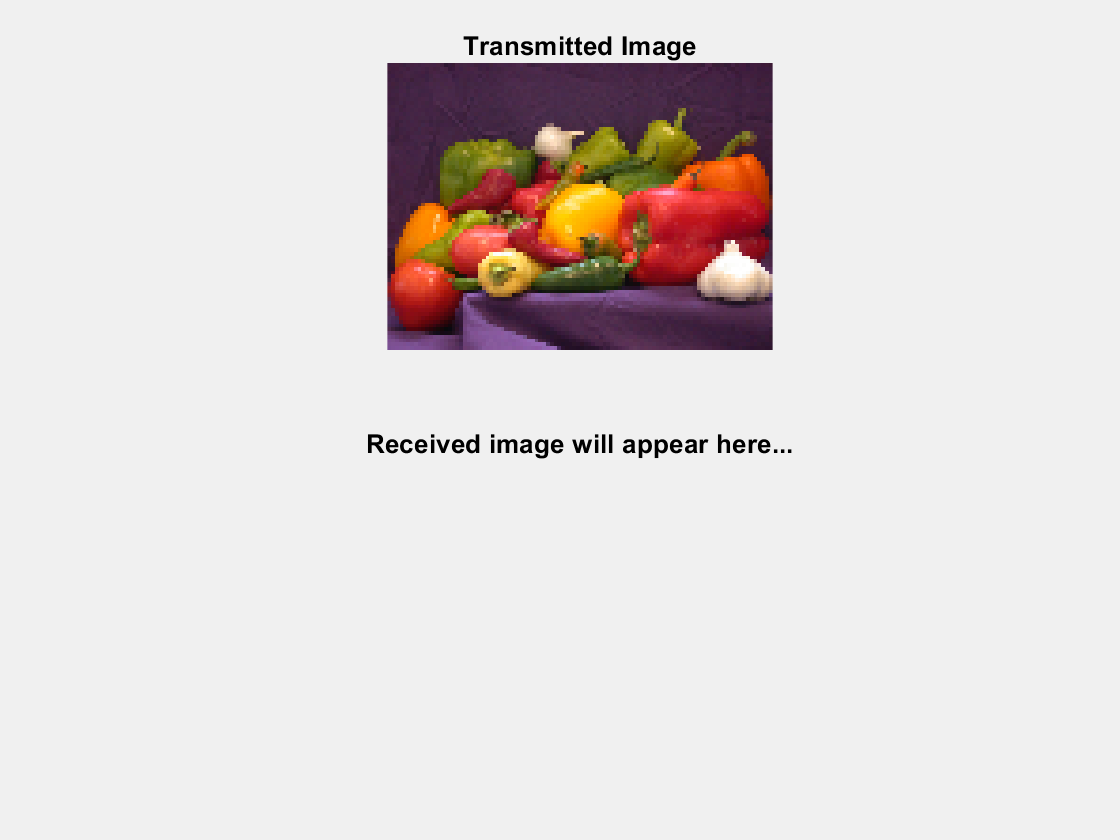

% Plot transmit image
figure(imFig);
imFig.Visible = 'on';
subplot(211);
    imshow(fData);
    title('Transmitted Image');
subplot(212);
    title('Received image will appear here...');
    set(gca,'Visible','off');

    set(findall(gca, 'type', 'text'), 'visible', 'on');

pause(1); % Pause to plot Tx image

msduLength = 2304; % MSDU length in bytes
numMSDUs = ceil(length(txImage)/msduLength);
padZeros = msduLength-mod(length(txImage),msduLength);
txData = [txImage; zeros(padZeros,1)];
txDataBits = double(reshape(de2bi(txData, 8)', [], 1));

% Divide input data stream into fragments
bitsPerOctet = 8;
data = zeros(0, 1);

numMSDUs=1

numMSDUs = 1

for ind=0:numMSDUs-1
%for ind=0:2

    % Extract image data (in octets) for each MPDU
    frameBody = txData(ind*msduLength+1:msduLength*(ind+1),:);

    % Create MAC frame configuration object and configure sequence number
    cfgMAC = wlanMACFrameConfig('FrameType', 'Data', 'SequenceNumber', ind);

    % Generate MPDU
    [mpdu, lengthMPDU] = wlanMACFrame(frameBody, cfgMAC);
    
    % Export the generated MAC frames to a PCAP file
    helperWLANExportToPCAP({mpdu}, 'macFrames.pcap');


    % Convert MPDU bytes to a bit stream
    psdu = reshape(de2bi(hex2dec(mpdu), 8)', [], 1);

    % Concatenate PSDUs for waveform generation
    data = [data; psdu]; %#ok<AGROW>

end

        2332



08
02
00
00
FF
FF
FF
FF
FF
FF
00
12
34
56
78
9B
00
12
34
56
78
9B
00
00
3F
43
3B
40
3E
42
3F
41
41
3E
3F
41
44
43
41
46
42
46
47
3F
3E
47
49
49
4B
4A
4B
49
49
49
47
40
48
3F
41
3E
3F
3E
47
46
4A
41
3F
44
3D
3D
44
45
4B
36
3C
2F
2E
2A
2B
2F
33
48
78
8F
8D
79
63
56
54
56
56
54
4E
46
4E
65
70
79
7B
7A
42
3F
40
3D
42
44
41
3F
42
3D
3F
44
42
44
43
43
45
40
3F
3A
37
40
4A
48
47
45
41
43
44
40
44
47
47
47
42
44
41
42
4A
43
49
4A
44
43
40
42
45
44
4A
3A
2F
3A
3D
31
28
50
C6
BD
B8
B1
A9
95
88
82
71
58
5A
4B
4A
44
3C
63
6B
79
7D
7D
44
42
42
43
3C
41
3C
3F
42
40
41
43
42
43
3F
3E
3B
3B
3E
3B
43
43
44
40
4D
46
46
46
41
44
45
40
40
42
42
40
47
49
45
47
45
46
45
44
45
45
49
4E
8A
B7
B7
BD
B6
AF
C2
D2
D7
D5
D8
CB
C1
B3
A3
93
81
77
68
48
44
3B
2F
5C
61
76
7D
7F
40
44
3F
44
42
42
44
45
46
44
41
41
3F
43
46
3B
44
3E
3F
46
40
43
48
45
43
46
44
47
47
49
44
43
45
45
47
43
43
40
46
3F
41
44
40
47
48
5A
BC
CF
D1
CF
CD
C5
BF
C6
E1
ED
EC
E3
E0
D3
C5
B9
AA
9C
8E
80
7C
77
5E
34
2A
5A
62
6F
7C
7E
3B
41
46
44
41
4

        2332



       18656



%radio = sdrtx(deviceNameSDR); % Transmitter properties
sdrTransmitter = comm.SDRuTransmitter('Platform','B200','SerialNum','310A880')

sdrTransmitter =   comm.SDRuTransmitter with properties:

                 Platform: 'B200'
                SerialNum: '310A880'
           ChannelMapping: 1
          CenterFrequency: 2.4500e+09
    LocalOscillatorOffset: 0
                     Gain: 8
                PPSSource: 'Internal'
              ClockSource: 'Internal'
          MasterClockRate: 32000000
      InterpolationFactor: 512
        TransportDataType: 'int16'
          EnableBurstMode: false



% Resample the transmit waveform at 30MHz
nonHTcfg = wlanNonHTConfig;         % Create packet configuration
fs = wlanSampleRate(nonHTcfg); % Transmit sample rate in MHz
osf = 1.5;                     % OverSampling factor
final_fs = fs*osf;
txGain = 50;
fc=2.472e9;
selected_tx = 1

selected_tx = 1

%interpolation = final_fs/sdrTransmitter.MasterClockRate
sdrTransmitter.MasterClockRate = final_fs

sdrTransmitter =   comm.SDRuTransmitter with properties:

                 Platform: 'B200'
                SerialNum: '310A880'
           ChannelMapping: 1
          CenterFrequency: 2.4500e+09
    LocalOscillatorOffset: 0
                     Gain: 8
                PPSSource: 'Internal'
              ClockSource: 'Internal'
          MasterClockRate: 30000000
      InterpolationFactor: 512
        TransportDataType: 'int16'
          EnableBurstMode: false


sdrTransmitter.InterpolationFactor = 1

sdrTransmitter =   comm.SDRuTransmitter with properties:

                 Platform: 'B200'
                SerialNum: '310A880'
           ChannelMapping: 1
          CenterFrequency: 2.4500e+09
    LocalOscillatorOffset: 0
                     Gain: 8
                PPSSource: 'Internal'
              ClockSource: 'Internal'
          MasterClockRate: 30000000
      InterpolationFactor: 1
        TransportDataType: 'int16'
          EnableBurstMode: false


sdrTransmitter.CenterFrequency = fc;  % Channel 1
sdrTransmitter.Gain = txGain;
sdrTransmitter.ChannelMapping = selected_tx;         % Apply TX channel mapping

info(sdrTransmitter)

ans = struct with fields:
                    Mboard: 'B200'
                  RXSubdev: 'FE-RX1'
                  TXSubdev: 'FE-TX1'
    MinimumCenterFrequency: 35000000
    MaximumCenterFrequency: 6.0150e+09
               MinimumGain: 0
               MaximumGain: 89.7500
                  GainStep: 0.2500
           CenterFrequency: 2.4720e+09
     LocalOscillatorOffset: 1.9069
                      Gain: 50
           MasterClockRate: 30000000
       InterpolationFactor: 1
        BasebandSampleRate: 30000000


nonHTcfg.MCS = 0;                   % Modulation: 64QAM Rate: 2/3
nonHTcfg.NumTransmitAntennas = 1;   % Number of transmit antenna
nonHTcfg.PSDULength = lengthMPDU;   % Set the PSDU length
%nonHTcfg.PSDULength = lengthMPDU;   % Set the PSDU length
nonHTcfg

nonHTcfg =   wlanNonHTConfig with properties:

             Modulation: 'OFDM'
       ChannelBandwidth: 'CBW20'
                    MCS: 0
             PSDULength: 2332
    NumTransmitAntennas: 1



% Initialize the scrambler with a random integer for each packet
scramblerInitialization = randi([1 127],numMSDUs,1);

% Generate baseband NonHT packets separated by idle time
txWaveform = wlanWaveformGenerator(data,nonHTcfg, ...
    'NumPackets',numMSDUs,'IdleTime',20e-6, ...
    'ScramblerInitialization',scramblerInitialization);

% Resample transmit waveform
txWaveform  = resample(txWaveform,fs*osf,fs);

fprintf('\nGenerating WLAN transmit waveform:\n')


Generating WLAN transmit waveform:



% Scale the normalized signal to avoid saturation of RF stages
powerScaleFactor = 0.9;
txWaveform = txWaveform.*(1/max(abs(txWaveform))*powerScaleFactor);
% Cast the transmit signal to int16, this is the native format for the SDR
% hardware
txWaveform_int = int16(txWaveform*2^15);
% Transmit RF waveform
%sdrTransmitter.transmitRepeat(txWaveform);

sdrTransmitter(txWaveform_int)

ans = uint32
0

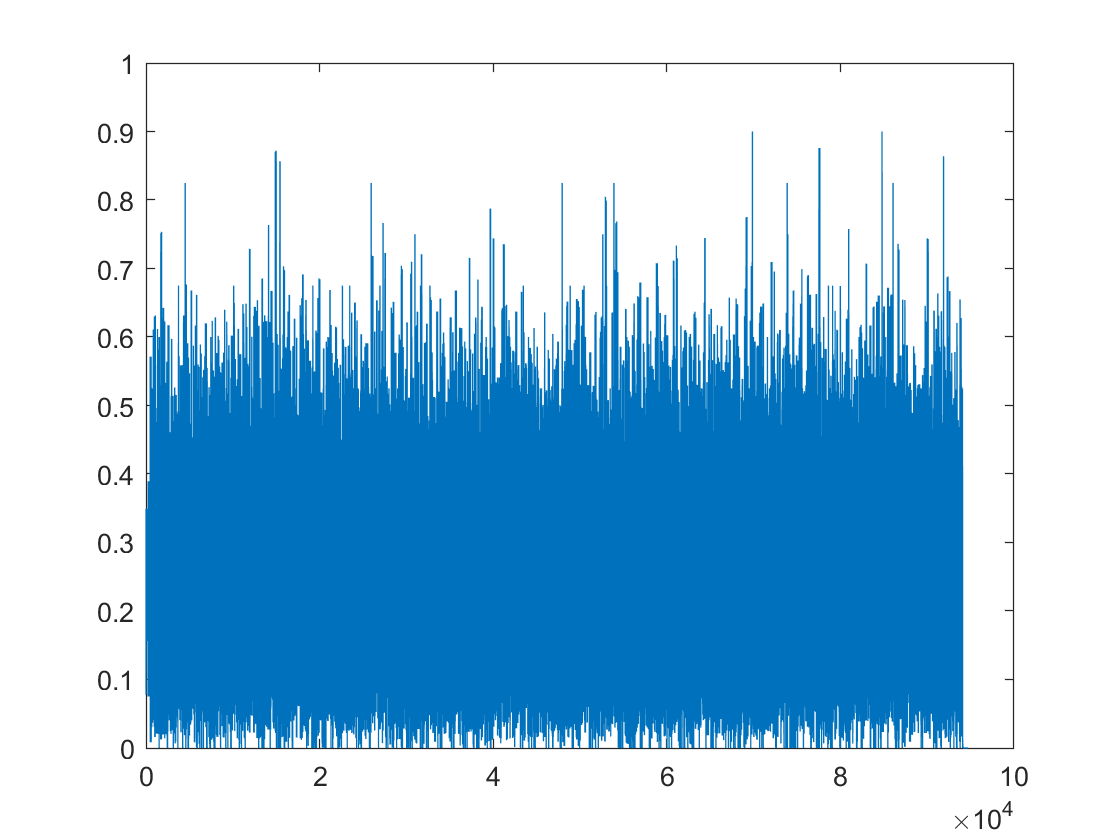

sdrTransmitter.release()
plot(abs(txWaveform))

t2 = load('test_2.mat')

t2 = struct with fields:
    packets: {1×20566 cell}


p1 = t2.packets{1}

p1 = 151×2 char array
    '88'
    '02'
    '2c'
    '00'
    '1c'
    '36'
    'bb'
    '1a'
    '43'
    '54'
    '10'
    '0d'
    '7f'
    '6d'
    '9c'
    'fd'
    '10'
    '0d'
    '7f'
    '6d'
    '9c'
    'fd'
    'e0'
    '53'
    '00'
    '00'
    'aa'
    'aa'
    '03'
    '00'
    '00'
    '00'
    '08'
    '00'
    '45'
    '00'
    '00'
    '71'
    'ef'
    'cf'
    '40'
    '00'
    '40'
    '11'
    'c6'
    'a2'
    'c0'
    'a8'
    '01'
    '01'
    'c0'
    'a8'
    '01'
    'b8'
    '00'
    '35'
    '91'
    '06'
    '00'
    '5d'
    '4e'
    '70'
    '4b'
    '19'
    '81'
    '80'
    '00'
    '01'
    '00'
    '01'
    '00'
    '00'
    '00'
    '00'
    '13'
    '69'
    '70'
    '76'
    '36'
    '2d'
    '63'
    '30'
    '31'
    '34'
    '2d'
    '62'
    '72'
    '75'
    '30'
    '30'
    '31'
    '2d'
    '69'
    '78'
    '01'
    '31'
    '03'
    '6f'
    '63'
    '61'
    '09'
    '6e'
    '66'
    '6c'
    '78'
    '76'
    '69'
    '64'
    '6

psdu_d = reshape(de2bi(hex2dec(p1), 8)', [], 1);
%psdu_d = double(psdu_t)
% Initialize the scrambler with a random integer for each packet
helperWLANExportToPCAP({p1}, 'macFrames_p1.pcap');

nonHTcfg = wlanNonHTConfig;         % Create packet configuration
nonHTcfg.MCS = 0;                   % Modulation: 64QAM Rate: 2/3
nonHTcfg.NumTransmitAntennas = 1;   % Number of transmit antenna
nonHTcfg.PSDULength = length(p1);   % Set the PSDU length

% Generate baseband NonHT packets separated by idle time
txWaveform_t = wlanWaveformGenerator(psdu_d,nonHTcfg)

txWaveform_t =    0.0654 + 0.2041i
  -1.1755 + 0.0208i
  -0.1196 - 0.6969i
   1.2670 - 0.1123i
   0.8165 + 0.0000i
   1.2670 - 0.1123i
  -0.1196 - 0.6969i
  -1.1755 + 0.0208i
   0.4082 + 0.4082i
   0.0208 - 1.1755i



% Resample transmit waveform
txWaveform_t  = resample(txWaveform_t,fs*osf,fs);

fprintf('\nGenerating WLAN transmit waveform:\n')


Generating WLAN transmit waveform:


% Scale the normalized signal to avoid saturation of RF stages
powerScaleFactor = 0.9;
txWaveform_t = txWaveform_t.*(1/max(abs(txWaveform_t))*powerScaleFactor);
% Cast the transmit signal to int16, this is the native format for the SDR
% hardware
txWaveform_t_int = int16(txWaveform_t*2^15);

sdrTransmitter(txWaveform_t_int)
sdrTransmitter.release()
plot(abs(txWaveform_t))

p1 = t2.packets{2}

p1 = 14×2 char array
    'd4'
    '00'
    '00'
    '00'
    '1c'
    '36'
    'bb'
    '1a'
    '43'
    '54'
    '95'
    'ae'
    '95'
    '83'


psdu_d = reshape(de2bi(hex2dec(p1), 8)', [], 1);
%psdu_d = double(psdu_t)
% Initialize the scrambler with a random integer for each packet
helperWLANExportToPCAP({p1}, 'macFrames_p1.pcap');

nonHTcfg = wlanNonHTConfig;         % Create packet configuration
nonHTcfg.MCS = 7;                   % Modulation: 64QAM Rate: 2/3
nonHTcfg.NumTransmitAntennas = 1;   % Number of transmit antenna
nonHTcfg.PSDULength = length(p1);   % Set the PSDU length

% Generate baseband NonHT packets separated by idle time
txWaveform_t = wlanWaveformGenerator(psdu_d,nonHTcfg)

txWaveform_t =    0.2786 + 0.6535i
  -1.1755 + 0.0208i
  -0.1196 - 0.6969i
   1.2670 - 0.1123i
   0.8165 + 0.0000i
   1.2670 - 0.1123i
  -0.1196 - 0.6969i
  -1.1755 + 0.0208i
   0.4082 + 0.4082i
   0.0208 - 1.1755i



% Resample transmit waveform
txWaveform_t  = resample(txWaveform_t,fs*osf,fs);

fprintf('\nGenerating WLAN transmit waveform:\n')


Generating WLAN transmit waveform:


% Scale the normalized signal to avoid saturation of RF stages
powerScaleFactor = 0.9;
txWaveform_t = txWaveform_t.*(1/max(abs(txWaveform_t))*powerScaleFactor);
% Cast the transmit signal to int16, this is the native format for the SDR
% hardware
txWaveform_t_int = int16(txWaveform_t*2^15);

sdrTransmitter(wave_int)

ans = uint32
0

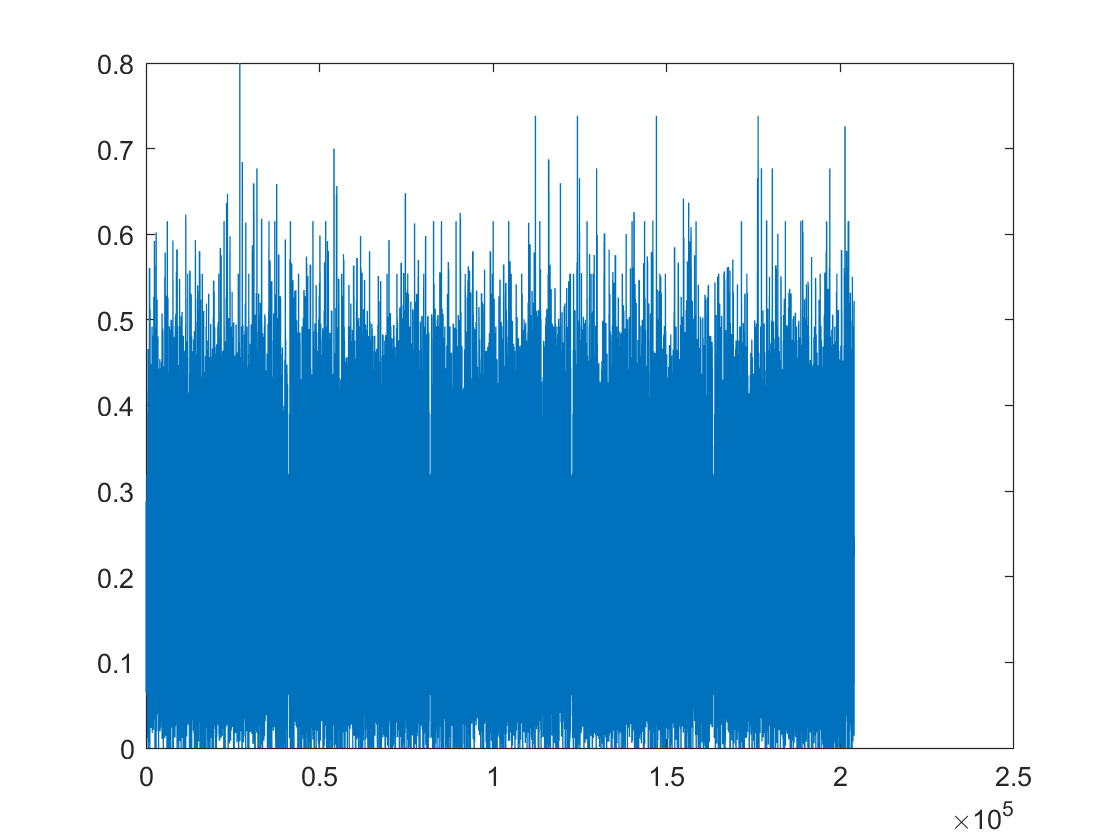

sdrTransmitter.release()
plot(abs(wave))

iter = 0

iter = 0

for ind_osf = 2.0:-0.5:1
    for ind_pow = 60:60
        for pa = 2:2
            for mcs_ind = 0:7
                disp(iter)
                disp(ind_osf)
                disp(pa)
                disp(ind_pow)
                disp( mcs_ind)
                iter=iter+1;
                fs = 20000000; % Transmit sample rate in MHz
                osf = ind_osf;                     % OverSampling factor
                final_fs = fs*osf;
                txGain = ind_pow;
                fc=2.472e9;
                selected_tx = 1;
                %interpolation = final_fs/sdrTransmitter.MasterClockRate
                sdrTransmitter.MasterClockRate = final_fs;
                sdrTransmitter.InterpolationFactor = 1;
                sdrTransmitter.CenterFrequency = fc;  % Channel 1
                sdrTransmitter.Gain = txGain;
                sdrTransmitter.ChannelMapping = selected_tx;         % Apply TX channel mapping
                
                p1 = t2.packets{pa};
                psdu_d = reshape(de2bi(hex2dec(p1), 8)', [], 1);
                %psdu_d = double(psdu_t)
                % Initialize the scrambler with a random integer for each packet
                helperWLANExportToPCAP({p1}, 'macFrames_2.pcap');
                
                nonHTcfg = wlanNonHTConfig;         % Create packet configuration
                nonHTcfg.MCS = mcs_ind;                   % Modulation: 64QAM Rate: 2/3
                nonHTcfg.NumTransmitAntennas = 1;   % Number of transmit antenna
                nonHTcfg.PSDULength = length(p1);   % Set the PSDU length
                
                % Generate baseband NonHT packets separated by idle time
                txWaveform_t = wlanWaveformGenerator(psdu_d,nonHTcfg);
                
                % Resample transmit waveform
                txWaveform_t  = resample(txWaveform_t,fs*osf,fs);
                
                fprintf('\nGenerating WLAN transmit waveform:\n')
                % Scale the normalized signal to avoid saturation of RF stages
                powerScaleFactor = 0.8;
                txWaveform_t = txWaveform_t.*(1/max(abs(txWaveform_t))*powerScaleFactor);
                % Cast the transmit signal to int16, this is the native format for the SDR
                % hardware
                txWaveform_t_int = int16(txWaveform_t*2^15);
                sdrTransmitter(txWaveform_t_int);
                sdrTransmitter.release();
                %plot(abs(txWaveform_t))'
            end
        end
    end
end

     0



     2



     2



    60



     0




Generating WLAN transmit waveform:


     1



     2



     2



    60



     1




Generating WLAN transmit waveform:


     2



     2



     2



    60



     2




Generating WLAN transmit waveform:


     3



     2



     2



    60



     3




Generating WLAN transmit waveform:


     4



     2



     2



    60



     4




Generating WLAN transmit waveform:


     5



     2



     2



    60



     5




Generating WLAN transmit waveform:


     6



     2



     2



    60



     6




Generating WLAN transmit waveform:


     7



     2



     2



    60



     7




Generating WLAN transmit waveform:


     8



    1.5000



     2



    60



     0




Generating WLAN transmit waveform:


     9



    1.5000



     2



    60



     1




Generating WLAN transmit waveform:


    10



    1.5000



     2



    60



     2




Generating WLAN transmit waveform:


    11



    1.5000



     2



    60



     3




Generating WLAN transmit waveform:


    12



    1.5000



     2



    60



     4




Generating WLAN transmit waveform:


    13



    1.5000



     2



    60



     5




Generating WLAN transmit waveform:


    14



    1.5000



     2



    60



     6




Generating WLAN transmit waveform:


    15



    1.5000



     2



    60



     7




Generating WLAN transmit waveform:


    16



     1



     2



    60



     0




Generating WLAN transmit waveform:


    17



     1



     2



    60



     1




Generating WLAN transmit waveform:


    18



     1



     2



    60



     2




Generating WLAN transmit waveform:


    19



     1



     2



    60



     3




Generating WLAN transmit waveform:


    20



     1



     2



    60



     4




Generating WLAN transmit waveform:


    21



     1



     2



    60



     5




Generating WLAN transmit waveform:


    22



     1



     2



    60



     6




Generating WLAN transmit waveform:


    23



     1



     2



    60



     7

